# Filters

# Audio Example

Here we load in a standard MATLAB sound file, 'handel'.

load handel
audiowrite('handel.wav',y,Fs)
[y, Fs] = audioread('handel.wav');
sound(y, Fs);
T = 1/Fs;
t = 0:T:(length(y)-1)*T;

Now we add a high-frequency (2500Hz) interference to the signal.

noise = 0.2*sin(2.*pi.*t.*2500).';
y = noise + y;
sound(y, Fs); 

We visualize the spectrum using a Fourier Transform.

N= 2^15;
S = fft(y,N);
S = fftshift(abs(S))/N;
F = Fs.*(-N/2:N/2-1)/N;

figure
plot(F,S)
title('Fourier Transform of Audio')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

# Filter Overview

## There are 4 main types of filters:

Lowpass - passes low frequencies through

Highpass - passes high frequencies through

Bandpass - passes a specific band

Bandstop - stops a specific band from going through

## There are primarily 4 implementations of filters

Butterworth - maxflat passband, monotonic passband & stopband

Chebychev I - equiripple passband, monotonic stopband

Chevychev II - monotonic passband, equiripple stopband

Elliptic - minimum order, equiripple passband & stopband

# Filter Design (GUI)

fdatool

Attenuation Pass = 1dB

Attenuation Stop = 80dB

Fpass = 1000

Fstop = 10000

Hd = getFilter
finalsound = Hd(y);
sound(finalsound,Fs);

# Filter Design (Code)

Generate a butterworth filter with Fs = 44100

Attenuation Pass = 1dB

Attenuation Stop = 80dB

Fpass = 1000

Fstop = 10000

Fs = 44100;
Apass = 1;
Astop = 80;
Fpass = 1e3;
Fstop = 1e4;
wpass = 2*Fpass/Fs; %normalized to nyquist freq.
wstop = 2*Fstop/Fs; %normalized to nyquist freq.


Other kinds of filters:

n = buttord([wpass],[wstop],Apass,Astop);
[b,a] = butter(n,[wpass]);
[H,W] = freqz(b,a);

% convert frequency to range 0 to Fs/2
f = W.*Fs/2/pi;
figure;
plot(f,20*log10(abs(H)));
title('Butterworth Lowpass Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');


# Image Example

## Low Pass Filtering

x = imread('pout.tif');
imshow(x);

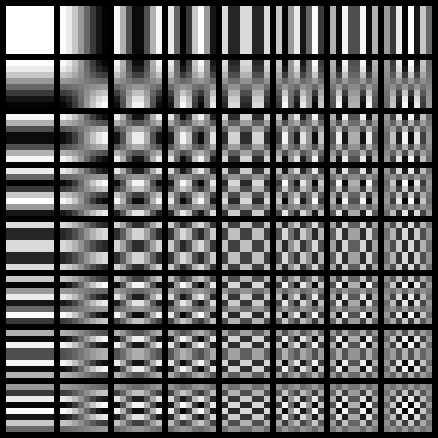


F = (fftshift(fft2(ifftshift(x))));

hpf_mask = zeros(size(F));
[H,W] = size(F);
hpf_mask(floor(H/2-H/10):floor(H/2+H/10),floor(W/2-W/10):floor(W/2+W/10)) = 1;

figure
subplot(121)
imshow(log(abs(F))/max(log(abs(F(:)))))
subplot(122)
imshow(hpf_mask)


im_filtered_fft = hpf_mask.*F;
f = fftshift(ifft2(ifftshift(im_filtered_fft)));
subplot(121)
fnorm = abs(f)/max(abs(f(:)));
imshow(fnorm)
subplot(122)
xnorm = abs(double(x))/max(double(x(:)));
imshow(xnorm)

## Basic Edge Detection

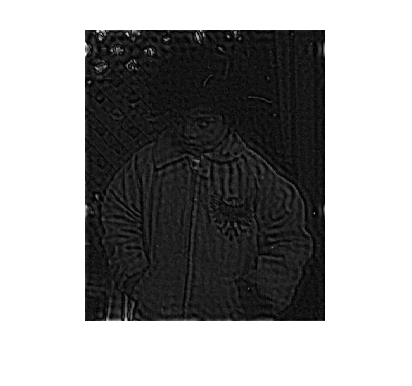

sharp_image = abs(0.9*fnorm-xnorm);
sharp_image_norm = sharp_image/max(sharp_image(:));
imshow(sharp_image_norm)

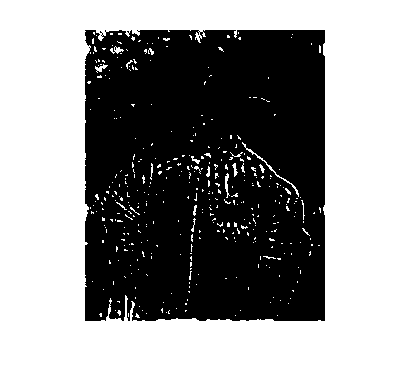

edge_image = zeros(size(sharp_image_norm));
edge_image(sharp_image_norm > 3.5*std(sharp_image_norm(:))) = 1;
imshow(edge_image)

# And now for something completely different...

 
$$\frac{-4s+8}{s^2+6s+8}$$


[r,p,k] = residue([-4, 8],[1, 6, 8])

r =    -12
     8


p =     -4
    -2



k =

     []



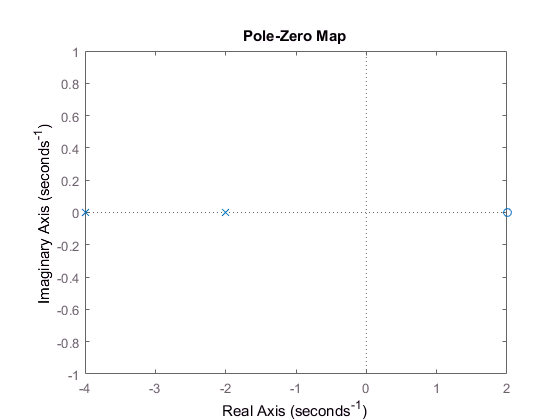

pzmap([-4, 8],[1, 6, 8])

syms t a s
f = exp(-a*t);
laplace(f)

$$ans = \frac{1}{a+s}$$

ilaplace(-4*s+8/(s^2+6*s+8))

$$ans = 4\,{\mathrm{e}}^{-2\,t}-4\,{\mathrm{e}}^{-4\,t}-4\,\delta^{\prime }(t)$$